# Single-Phase Photovoltaic (PV) System

## **Before you get started**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternatively, select **Hide Code **using the icon   at the top right of the Live Editor pane.

Some interactions require basic MATLAB familiarity. If you need a refresher, MATLAB Onramp is a free, two-hour tutorial that covers the essentials.[](https://www.mathworks.com/learn/tutorials/matlab-onramp.html)

Work through the sections in order. Some sections use variables created earlier, so running sections out of sequence may produce errors.

## 1. Introduction

A single-phase photovoltaic (PV) system converts solar energy into DC power, then uses power electronics to produce AC power for grid integration or local loads. In this activity, you will focus on a key challenge in single-phase systems: double-frequency power oscillations that create second-order harmonics and can increase total harmonic distortion (THD).

To reduce second-order harmonics, techniques such as notch filtering, proportional-integral control, dual-loop control systems, and DC-link decoupling strategies are implemented.

By the end of this activity, you should be able to explain why single-phase PV systems produce pulsating power, how the boost converter and DC-link capacitor reduce its effect, and how MPPT and inverter control support grid-connected operation.

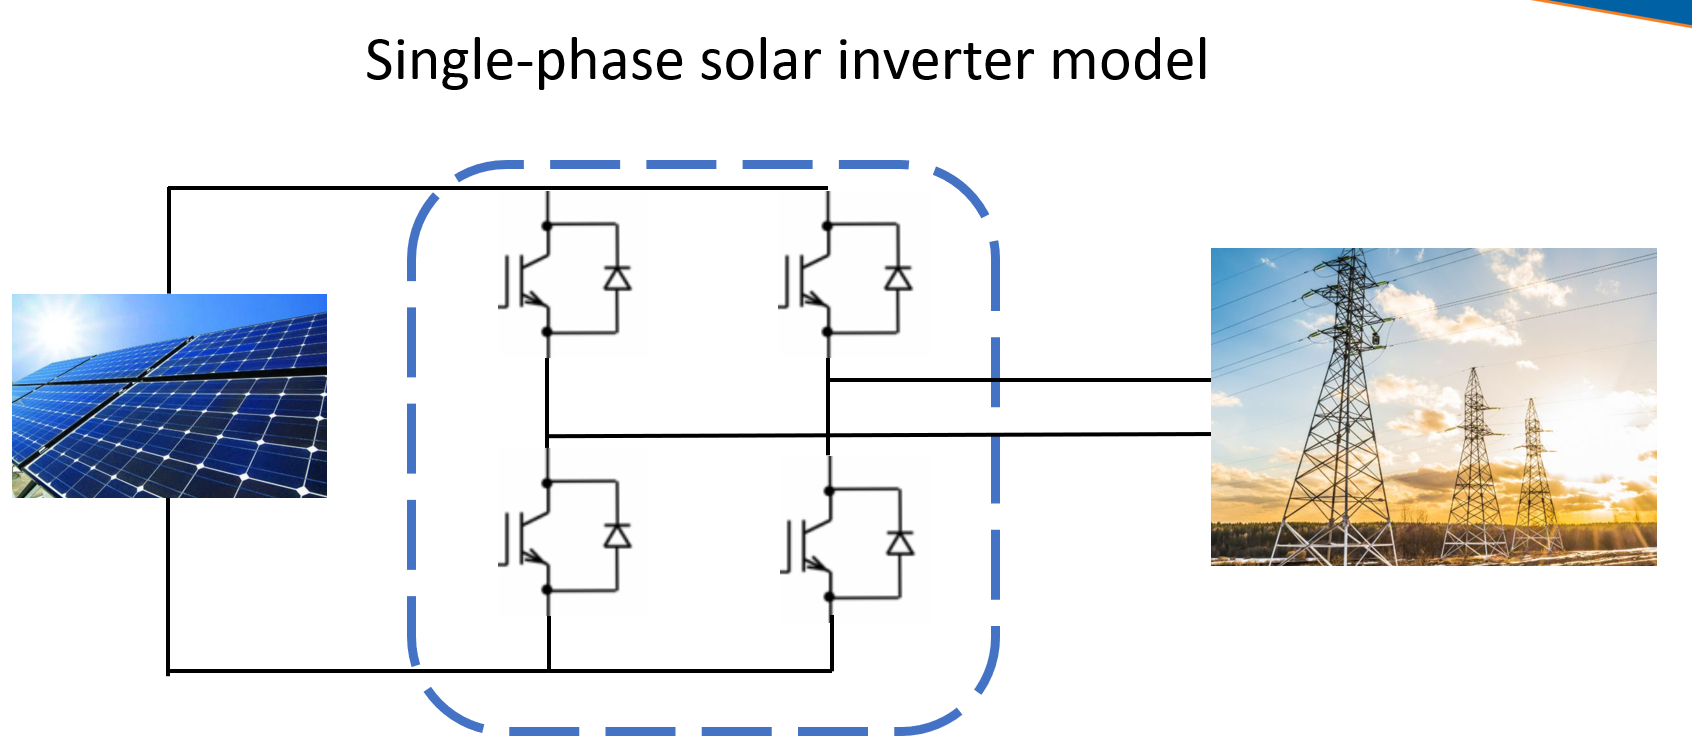

The structure of the single-phase PV system 

## 2. Pulsating Power

One key difference between a three-phase PV power system and a single-phase PV power system is the presence of “pulsating power.” Since both the grid voltage and the inverter output are sinusoidal signals, the instantaneous power $p=U\times \;I$ will contain a second-order harmonic component. This harmonic reflects back to the PV panel, causing its voltage to fluctuate. As a result, the PV system cannot maintain a stable operating point at Maximum Power Point Tracking (MPPT), which reduces energy efficiency, shortens the equipment lifespan, and degrades the quality of the electricity supplied. 

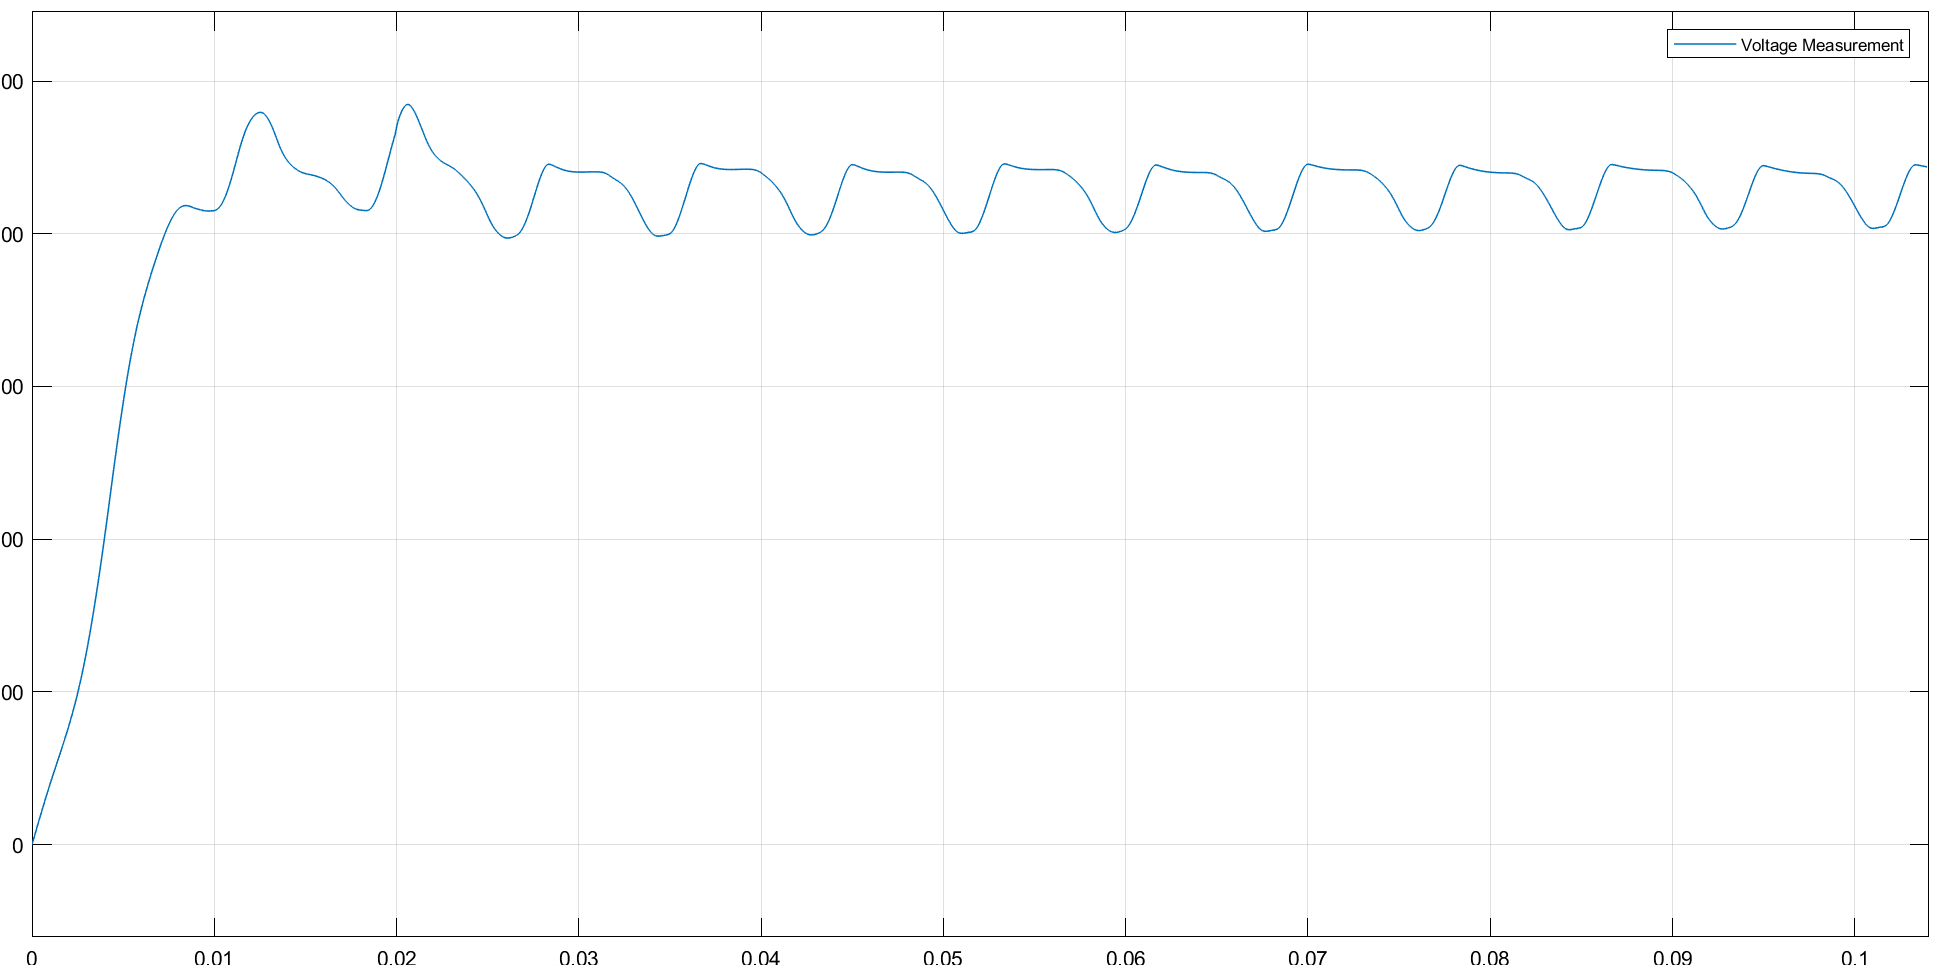

Second-order (120 Hz) harmonics appear in the PV voltage

To address this issue, a larger capacitor and a boost converter are introduced. The boost converter acts as a filter, removing second-order harmonics from the inverter output. At the same time, the large capacitor absorbs the pulsating power, further reducing the impact of these harmonics.

## 3. Circuit

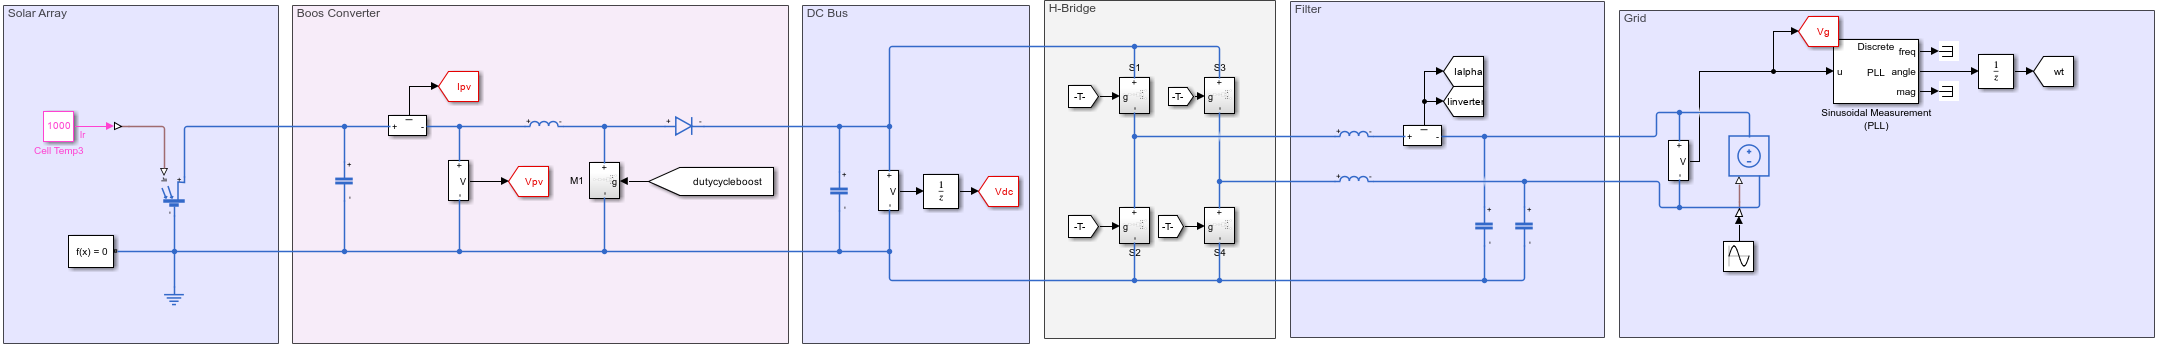

The circuit above shows the solar array connected to the power grid through a single-phase inverter and a filter. 

Click the button below to learn more about different sections of the model: 

switchRectifier("No Selection");

### 3.1 Solar Panel

Photovoltaic (PV) technology converts solar irradiance into electrical power using semiconductor materials. In this section, connect the physical PV module to the I-V and P-V curves that determine how much power the system can extract.

The image below shows a real PV module.

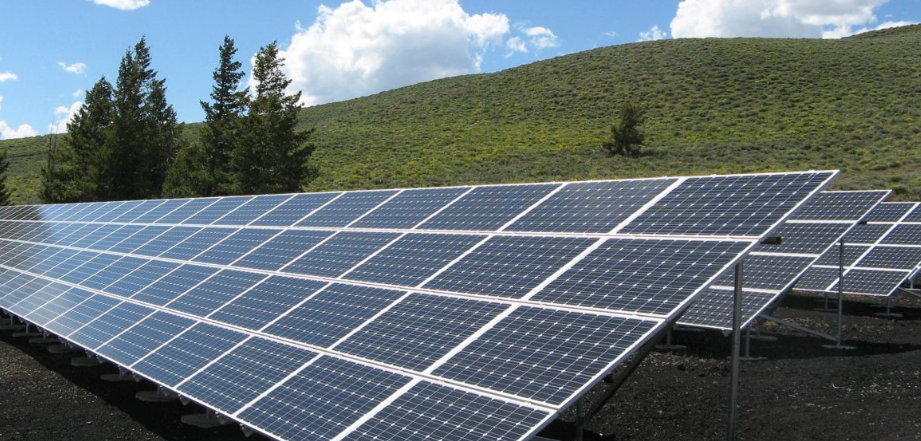

**An I-V curve shows the relationship between current and voltage under specified irradiance and temperature conditions, commonly 1000 **$\bm{w}/{\bm{m}}^2$** and 25 degrees Celsius.**

The following Simulink model shows the detailed structure of the PV model: 

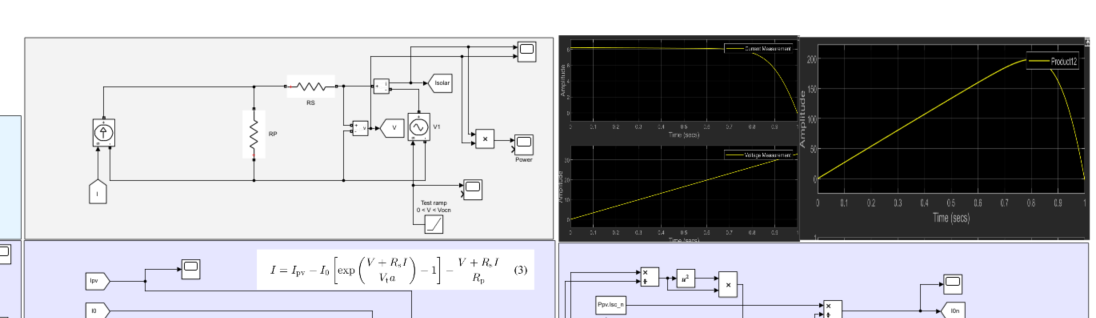

Open the detailed PV model and identify where irradiance and temperature enter the model.

 
open_system('Models/SinglePhasePVModule.slx')

Before moving the sliders, predict how lower irradiance or higher temperature will affect the I-V and P-V curves. Then adjust the irradiance and temperature and compare the plots with your prediction.

Irradiance=700;
Temperature=51;
 
pv_curves(Irradiance, Temperature);

### 3.2 Single-Phase PV Circuit Simulation

Let's turn our attention back to the full PV circuit.

Before running, predict which signals should settle and which may show ripple. Then click Open & Run and inspect the model behavior.

After the simulation is complete (allow a few minutes), use the following plots to connect the circuit behavior with the controller objectives:

- DC Output Voltage

- Inverter Current

- Output Power

- PV Voltage

disp("Please wait for the simulation to finish. This may take a few minutes")
open_system('Models/one_phase_PV_Final.slx')
warning('off','all')
simOut = sim('Models/one_phase_PV_Final.slx','ReturnWorkspaceOutputs','on');
runmodel_onephasePV(simOut);
disp("Simulation completed. You can now analyze the results")

### 3.3 Grid Connection

For this simulation, the inverter output must match the grid frequency and phase angle. A phase-locked loop (PLL) estimates the grid phase and frequency. You do not need to analyze the PLL internals here; focus on how synchronization supports grid connection.

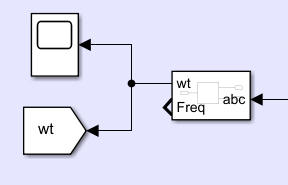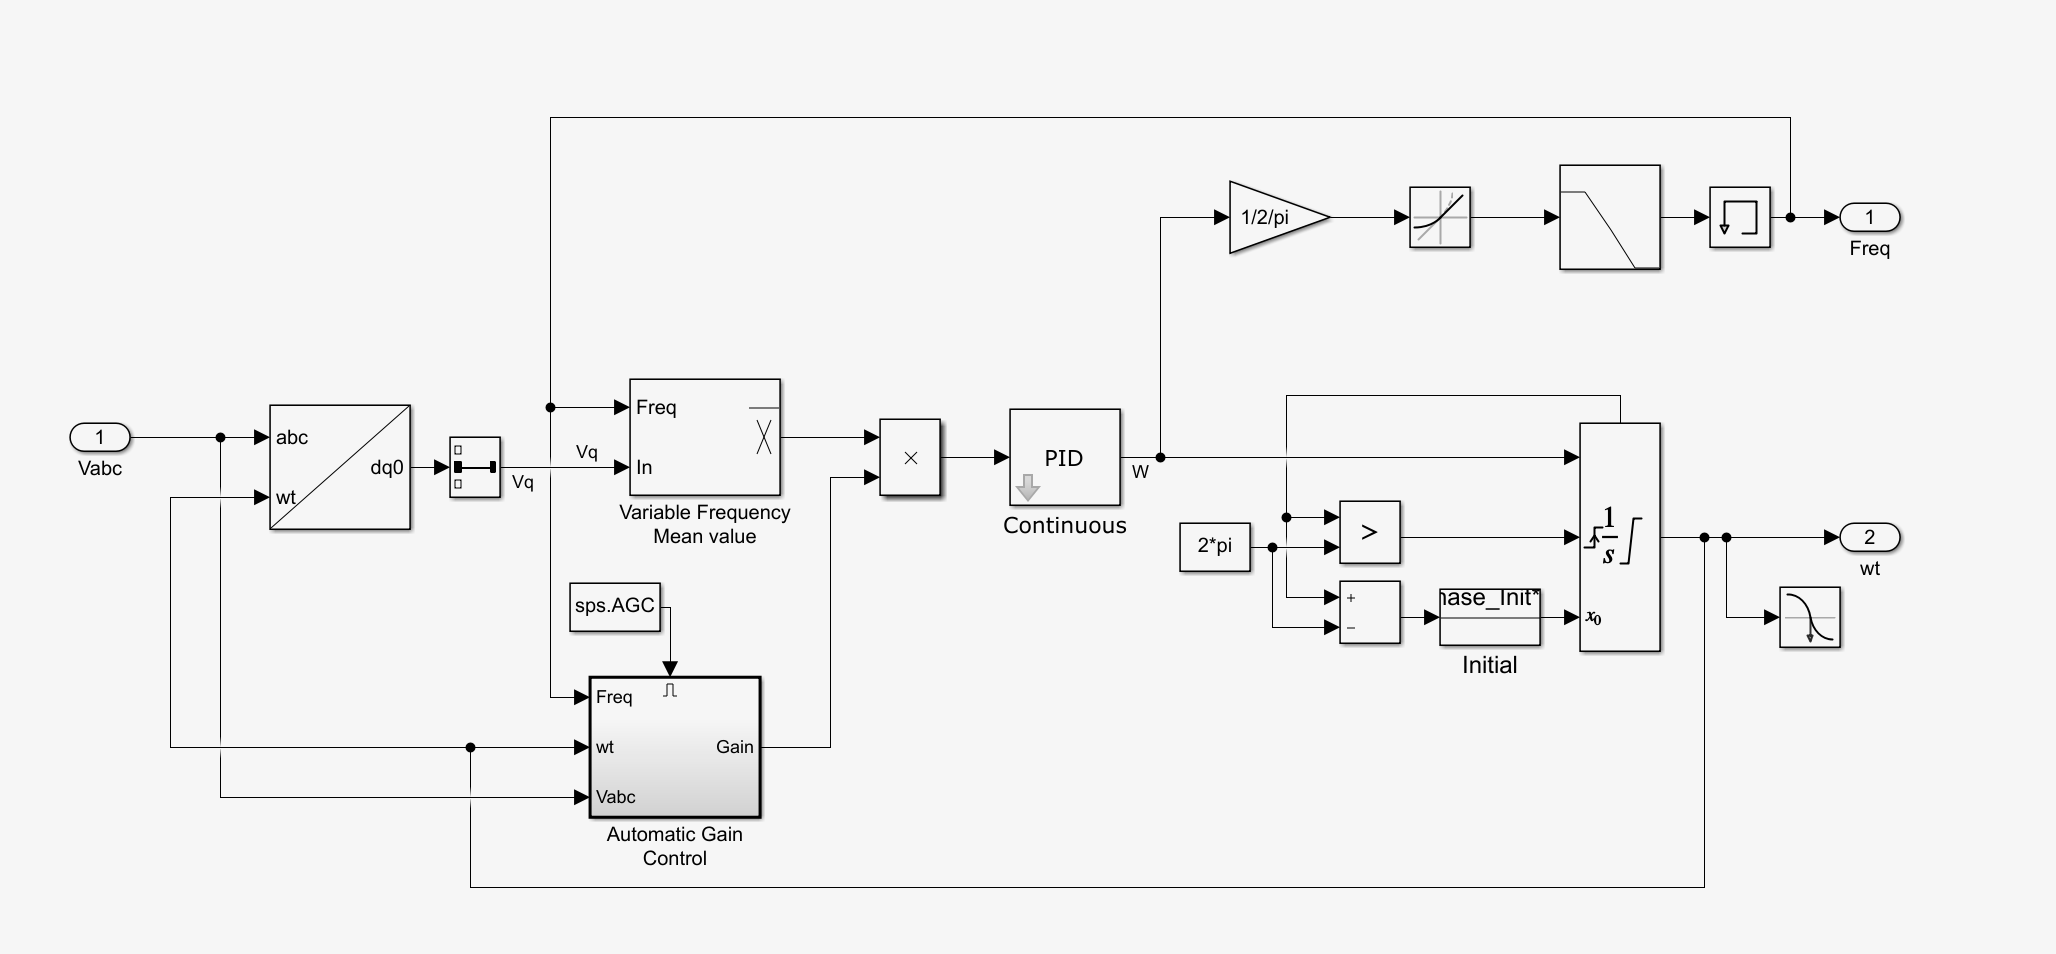

## 4. Control Algorithm

The control algorithm has three parts:

- The maximum power point tracking (MPPT) algorithm

- Boost converter control 

- DC bus control

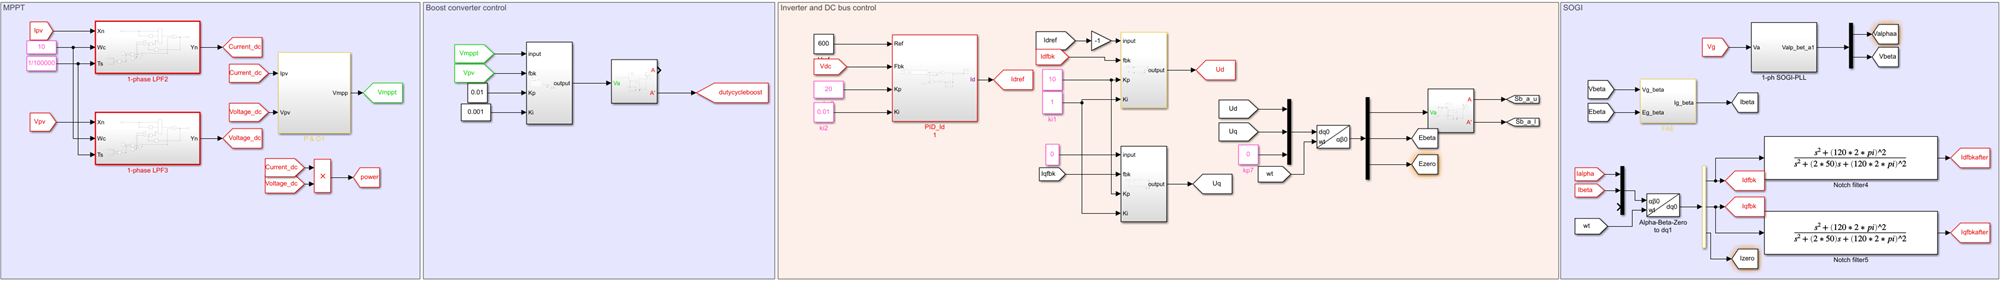

### 4.1 Maximum Power Point Tracking (MPPT)

MPPT control adjusts the PV operating point so the array stays near the maximum of the power-voltage curve. This point is called the maximum power point (MPP), and it changes when irradiance or temperature changes.

Two common MPPT methods are perturbation and observation (P&O) and incremental conductance. This model uses the P&O method.[](https://www.mathworks.com/discovery/mppt-algorithm.html)

MPPT("No Selection")

As you run the model, watch whether Vmppt settles near the operating point selected by the MPPT controller.

### 4.2 Boost converter control

A proportional-integral (PI) controller generates the switch duty cycle. Before opening the details, predict how increasing the duty cycle should affect the boost converter output voltage.

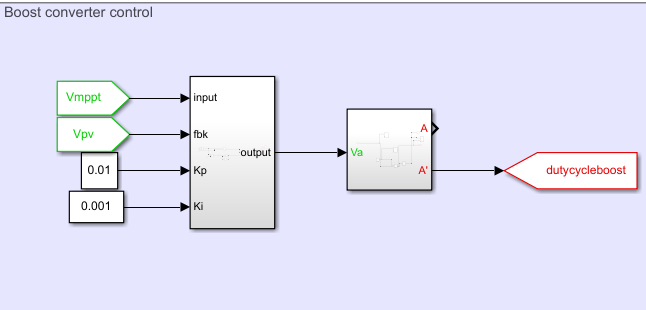


showpic1(false)

### 4.3 Inverter and DC Bus Control

The inverter control combines current control, voltage control, and duty-cycle generation.

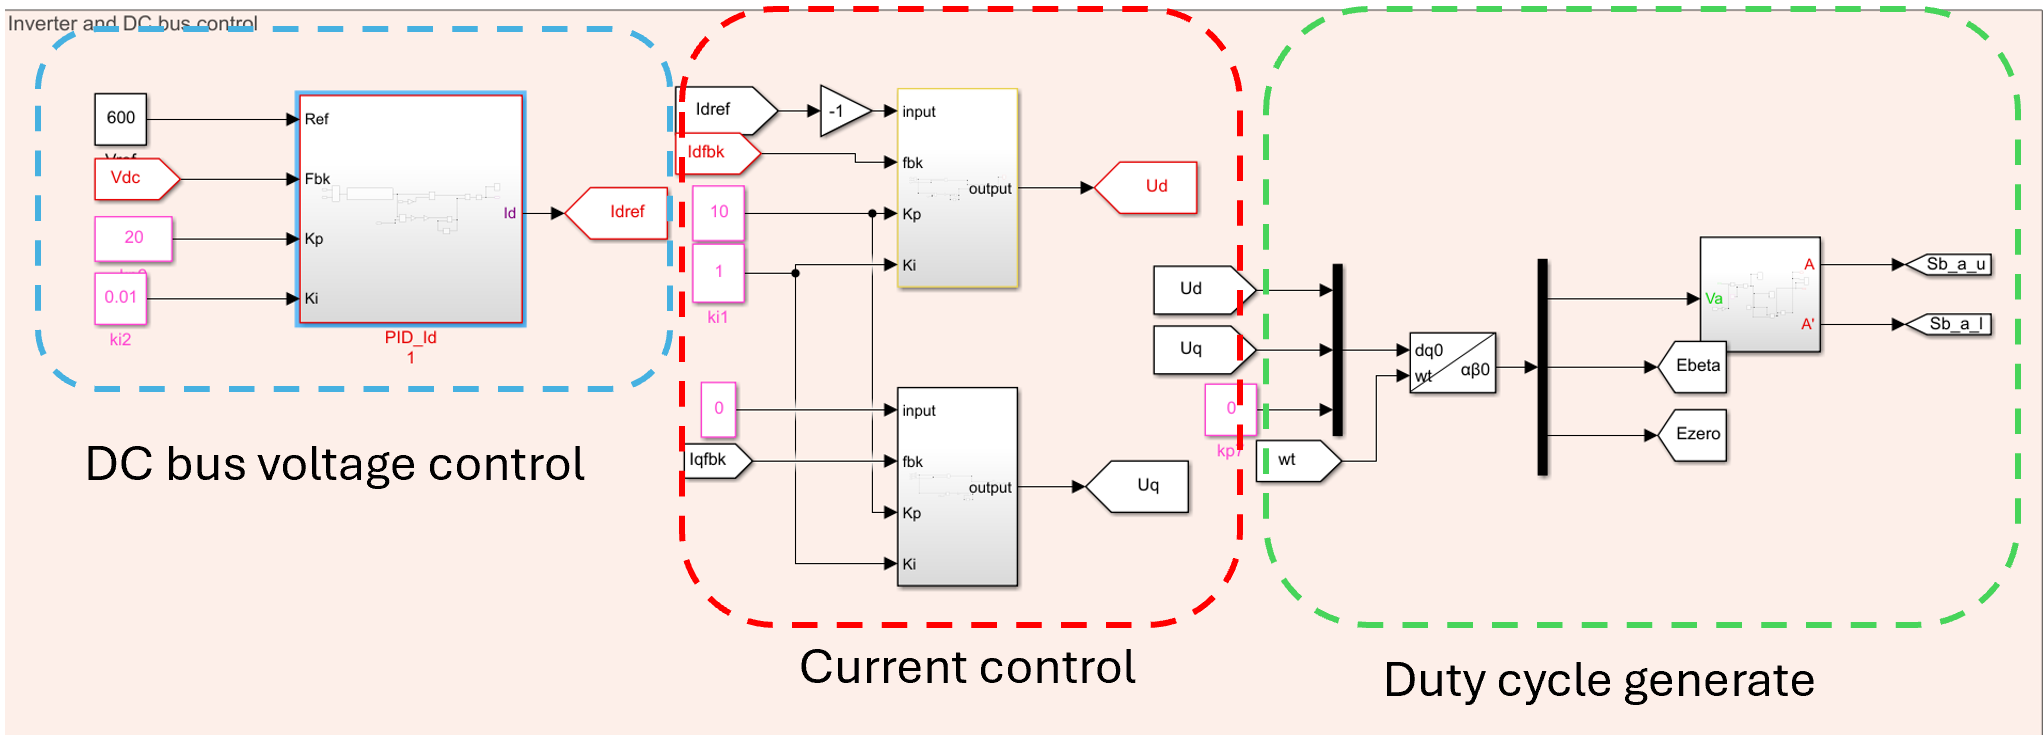

Use the drop-down menu to inspect each controller and connect it to the signals you observed in simulation.

controller("No Selection")

### 4.4 Second-Order Generalized Integrator (SOGI)

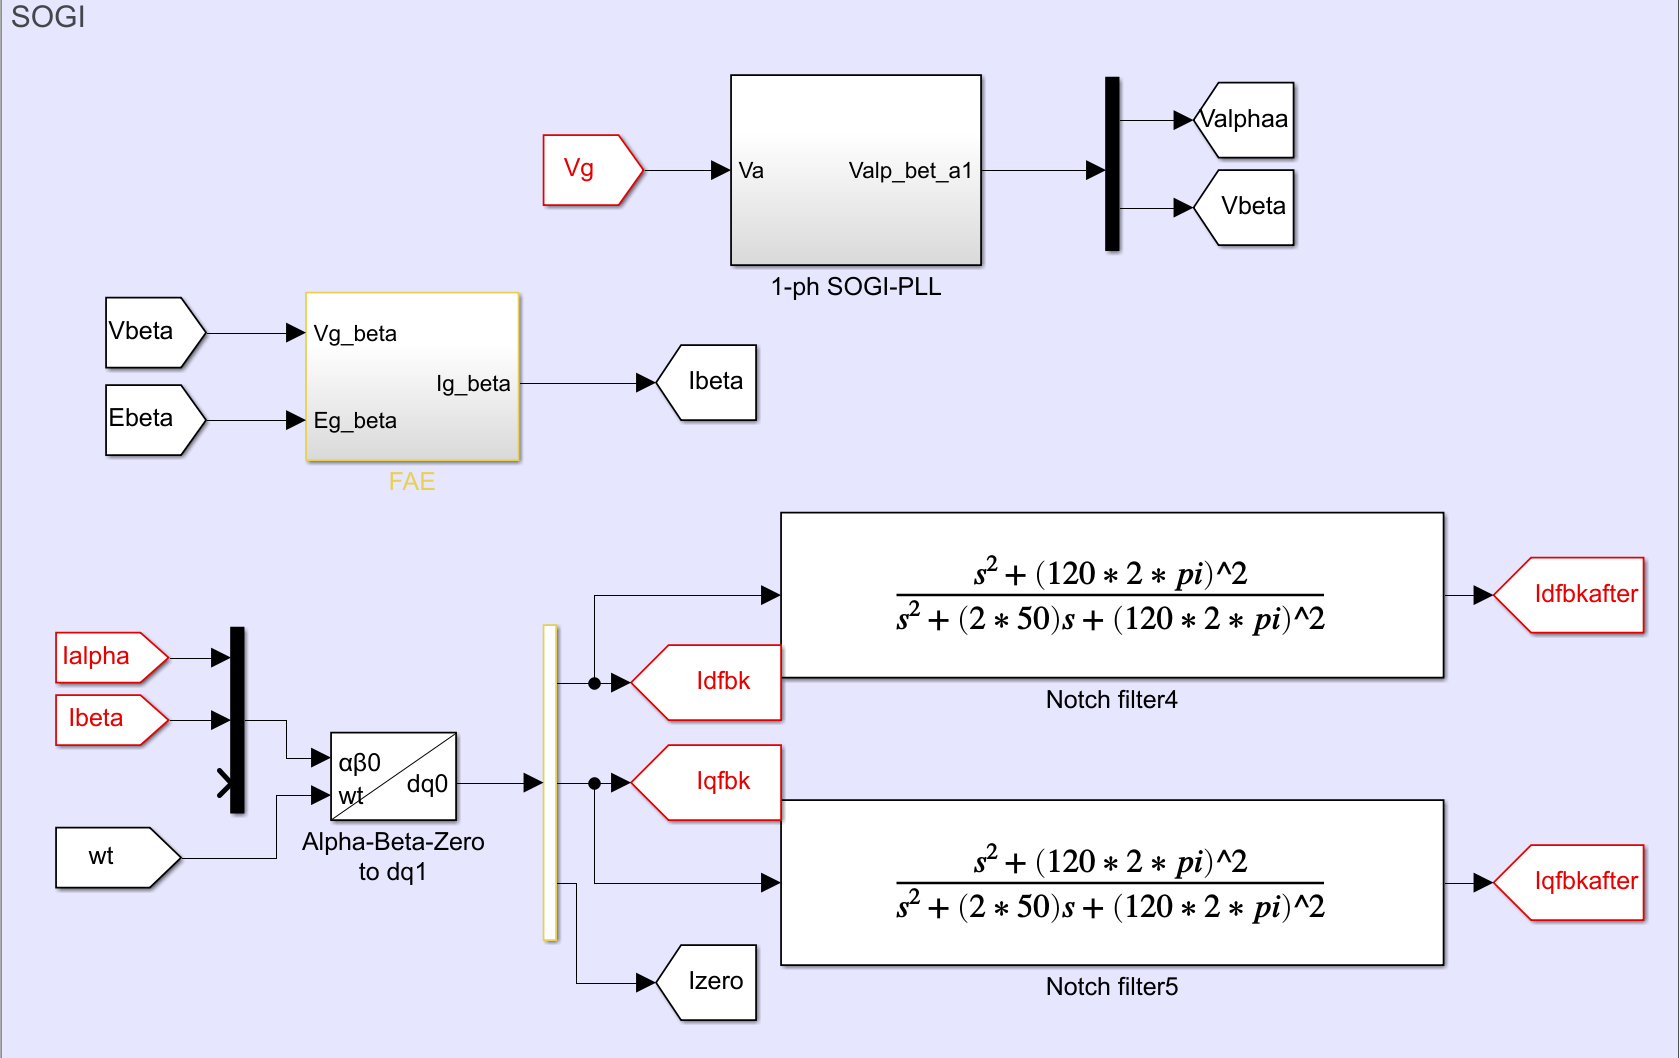

A key difference between single-phase and three-phase systems is that a single measured phase does not directly provide the orthogonal signal needed for the alpha-beta-to-dq transformation. The SOGI generates a virtual beta voltage, which is then used to calculate a virtual beta current and improve current-controller performance.

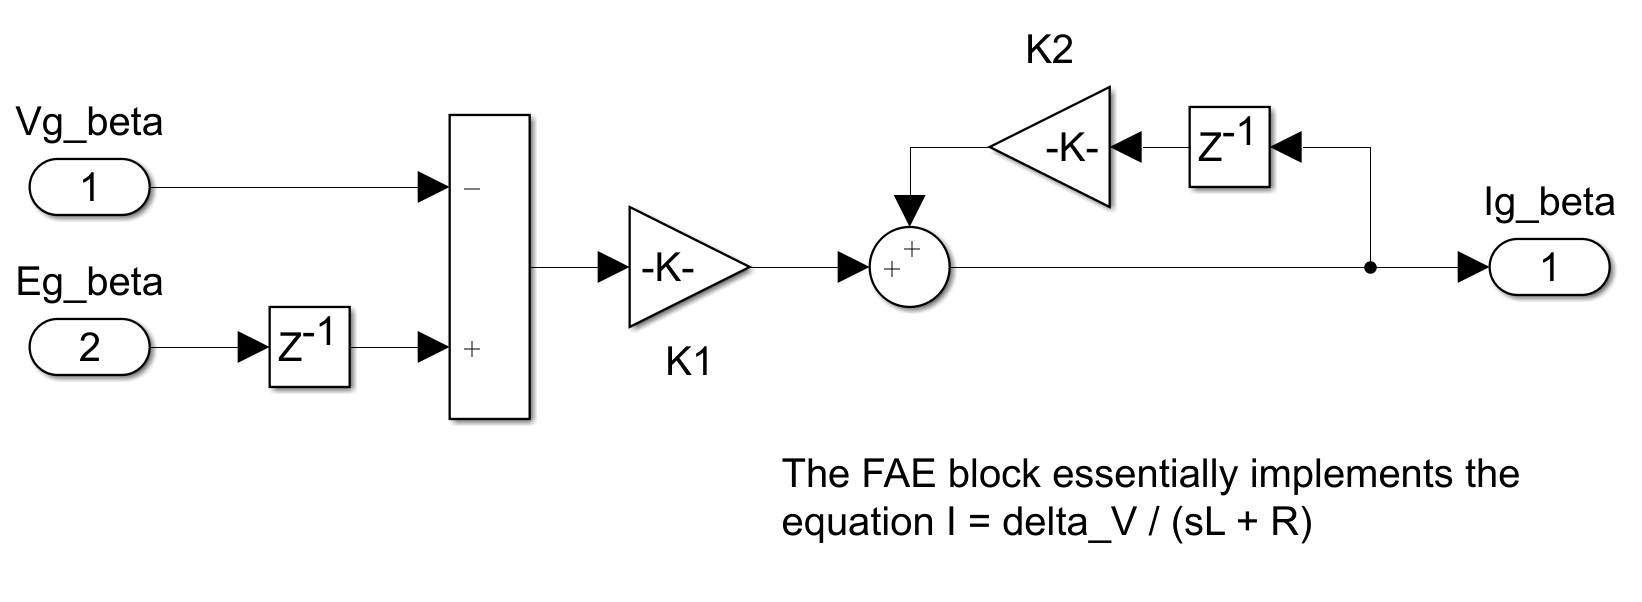

Vg_beta is the voltage generated by the SOGI, and Eg_beta is the voltage calculated from the inverter. 

## 5. Analyzing Model Results

Run the single-phase solar model. Once the simulation is complete (allow a few minutes), use the scopes to evaluate whether the controller met its objectives.

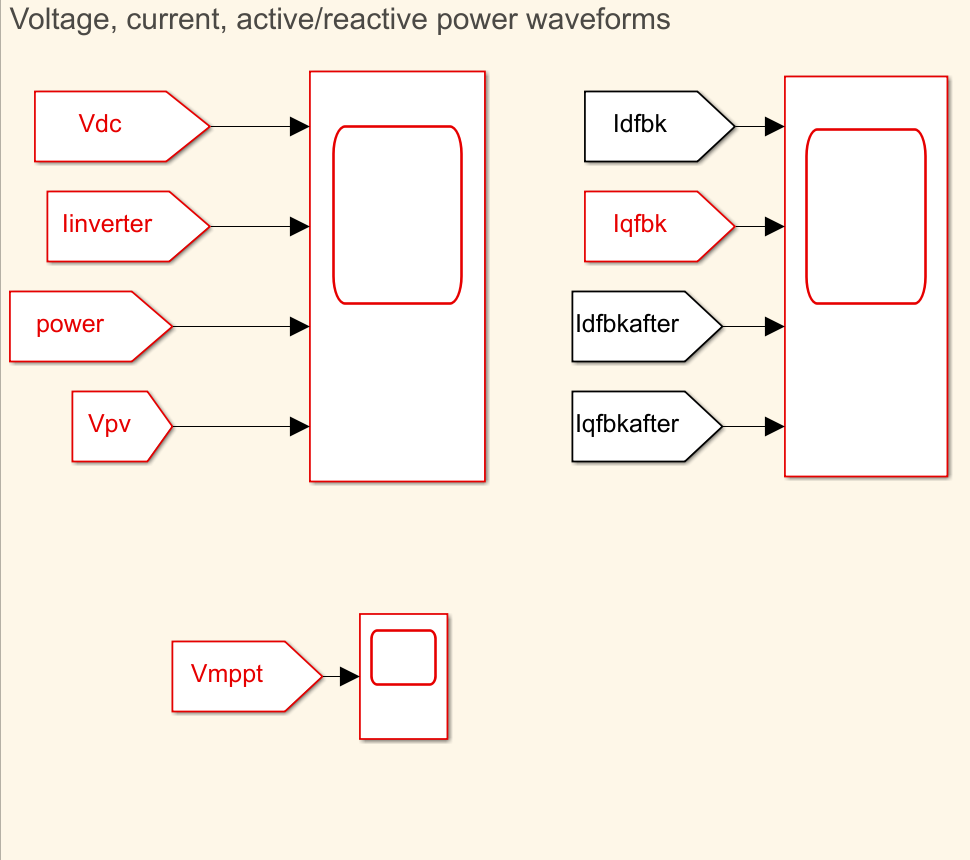

Use the plots to answer these questions:

- Is Vdc stable at the MPPT point?

- Is the inverter current a smooth sine wave?

- Do second-order harmonics appear on the DC bus voltage?

If the simulation results satisfy the above conditions, Id, Iq, and Vmppt are stable. This means the control algorithm is doing its job.  

Use the menu below to compare your results with the reference simulation results.

result("No Selection")

## 6. Conclusion

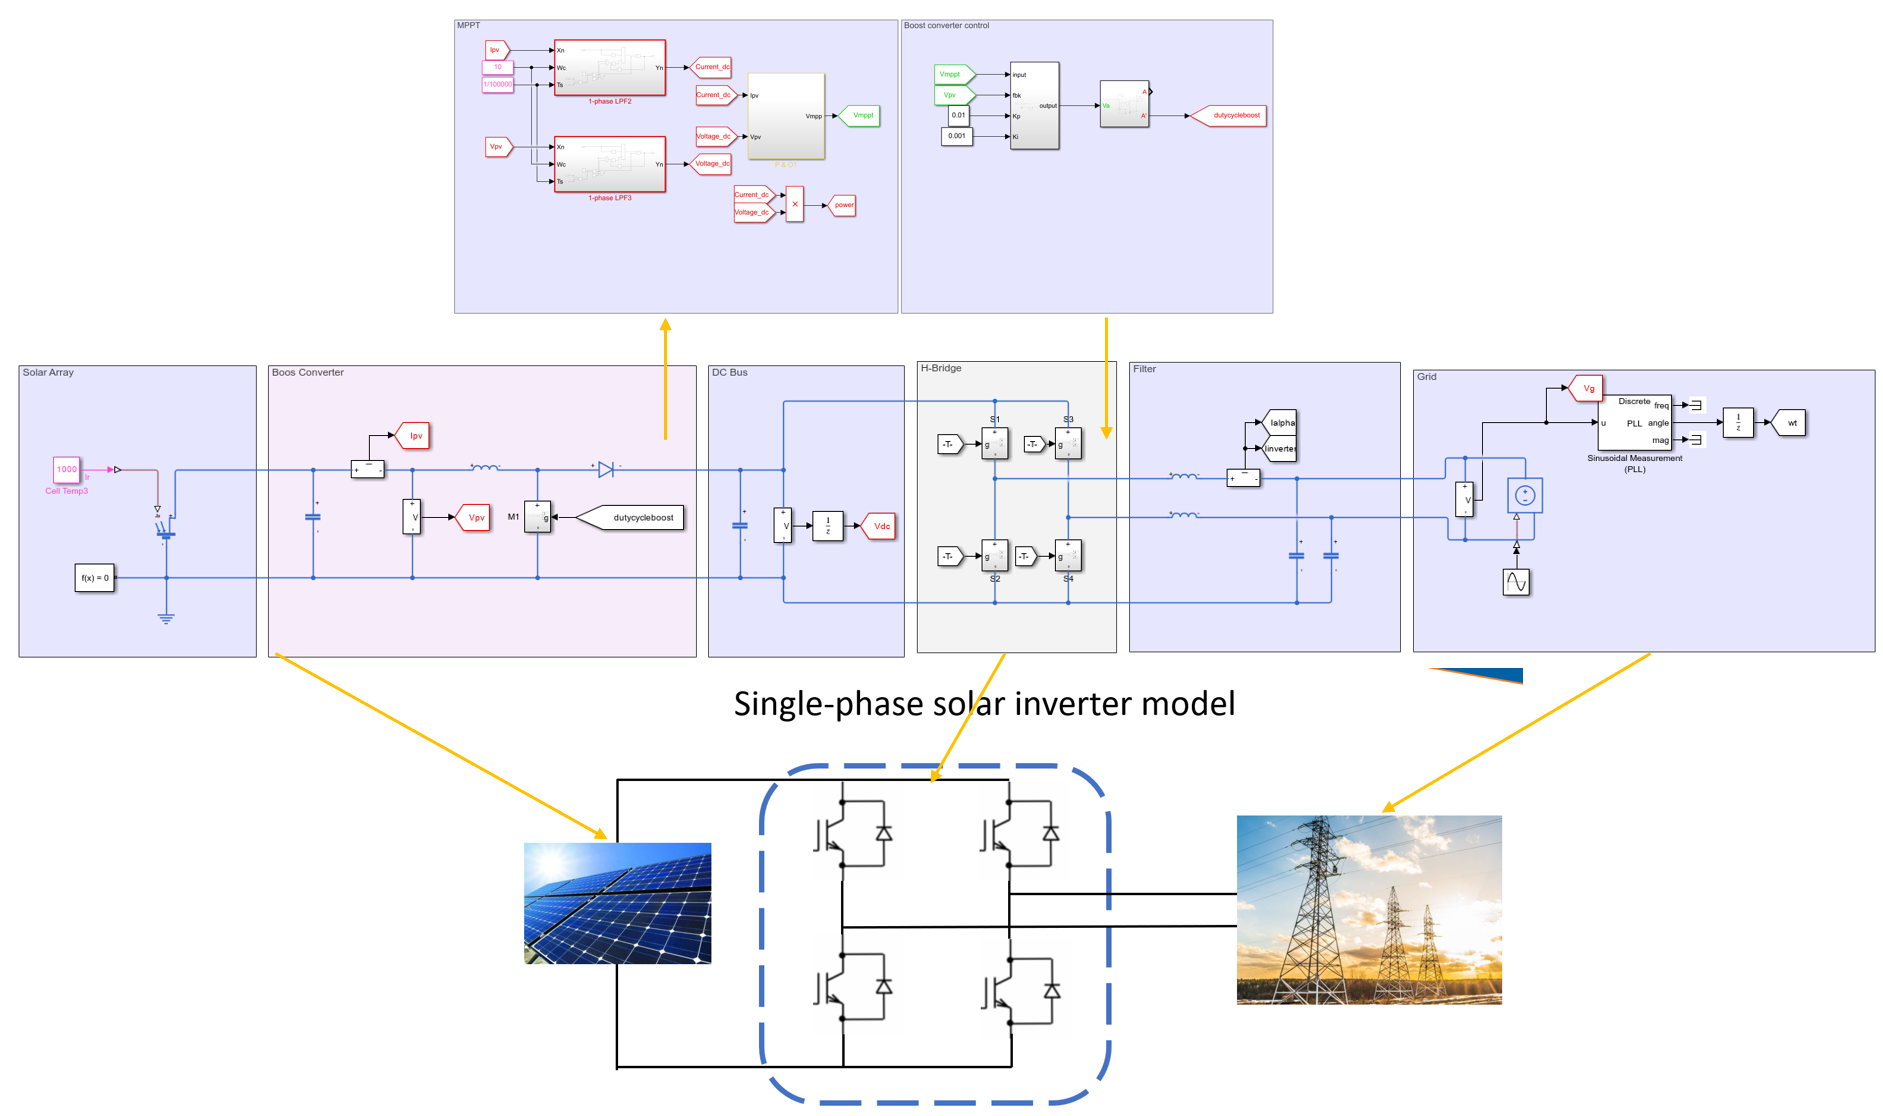

This single-phase PV simulation connects PV array behavior, boost converter operation, inverter control, and grid synchronization in one model. It shows how the controller converts PV power into grid-compatible AC power while limiting the effect of second-order harmonics on MPPT operation.

Key takeaways from this model include:

- **Pulsating Power Problem**: Single-phase systems inherently suffer from 120 Hz second-order harmonics due to double-frequency oscillations in AC power. These harmonics affect the PV output voltage and MPPT stability.

- **Mitigation Strategy**: The use of a **large capacitor** and a **boost converter** helps to suppress pulsating power and stabilize the DC link voltage. This improves overall power quality and protects PV panel performance.

- **MPPT**: The model employs the P&O algorithm to track the optimal power output point, maximizing energy harvested under varying irradiance and temperature conditions.

- **Inverter and Control Architecture**: The Inverter control consists of DC bus voltage regulation and current control using **PI controllers**, along with **duty cycle generation** for modulation.

- **SOGI Implementation**: To overcome limitations of the αβ-dq transformation in single-phase systems, the model uses a **SOGI** to generate virtual orthogonal signals for better current control performance.

The irradiance and temperature sliders let you connect physical operating conditions to changes in the I-V and P-V curves.

After completing this activity, you should be able to explain how PV conversion, MPPT, and inverter control work together in a grid-connected single-phase PV system.

## 7. Exercises

Exercise 1. Which transformation is used in this model? Reflect on why this is needed for the controller.

exerciseSol1(...
     false, ...
   false);
 

Exercise 2. What are the two major control targets in the control algorithm? Also, ponder on which signals show whether they are being met.

exerciseSol2(...
     false, ...
   false,...
  false);
 

Exercise 3. Which part of the circuit mitigates the pulsating-power problem? Use the simulation plots to support your answer.

exerciseSol3(...
     false, ...
   false,...
   false);
 

function switchRectifier(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "Solar Panel" "Grid" "Booster-Controller" "Hbridge"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Solar Panel"
        rect = imread("Images/SinglePhasePV/PV.png");
        imshow(rect,'Interpolation',"bilinear");
        fprintf('test')
    elseif opt == "Grid"
        rect = imread("Images/SinglePhasePV/grid.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Booster-Controller"
        rect = imread("Images/SinglePhasePV/BoosterController.png");
        imshow(rect, 'Interpolation', 'bilinear');
    elseif opt == "Hbridge"
        rect = imread("Images/SinglePhasePV/Hbridge.png");
        imshow(rect, 'Interpolation', 'bilinear');
    end
end
end

function MPPT(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "P&O" "Incremental Conductance"])}
end
clf;
if opt == "No Selection"
else
    if opt == "P&O"
        rect = imread("Images/SinglePhasePV/PO.jpg");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Incremental Conductance"
        rect = imread("Images/SinglePhasePV/IC.jpg");
        imshow(rect,"Interpolation","bilinear");
    end
end
end

function controller(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "DCbus control" "Inverter control" "SPWM"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Inverter control"
        rect = imread("Images/SinglePhasePV/controller.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "SPWM"
        rect = imread("Images/SinglePhasePV/SPWM.png");
        imshow(rect,"Interpolation","bilinear");
    elseif opt == "DCbus control"
        rect = imread("Images/SinglePhasePV/dcbus.png");
        imshow(rect,"Interpolation","bilinear");
    end
end
end

function result(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "Circuit Parts" "Control Part"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Circuit Parts"
        rect = imread("Images/SinglePhasePV/Result1.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Control Part"
        rect = imread("Images/SinglePhasePV/Result2.png");
        imshow(rect,"Interpolation","bilinear");
    end
end
end


function pv_curves(Irradiance, Temperature)
    V = linspace(0, 32.9, 100);  
    T = Temperature + 273;  
    G = Irradiance;
    k = 1.38064852e-23;
    q = 1.602176634e-19;
    Ns = 54;
    Voc_n = 32.9;
    Isc_n = 8.21;
    Rs = 0.2210;
    Rp = 415.405;
    a = 1.3;
    Eg = 1.12;
    KI = 0.0032;
    Ipv_n = 8.21;
    G_n = 1000;
    T_n = 298;
    Vt = Ns * k * T / q;
    
    I0 = calculate_saturation_current(T, T_n, Isc_n, Voc_n, Eg, a);
    Ipv = calculate_pv_current(Ipv_n, KI, (T - T_n), G, G_n);
    
 
    I_values = arrayfun(@(v) calculate_current(Ipv, I0, Rs, Rp, v, Vt, a), V);
    
  
    P = V .* I_values;
    
    figure('Position', [100, 100, 1200, 400]);  
    subplot(1, 2, 1); 
    plot(V, I_values, 'b', 'LineWidth', 2); 
    title('I-V Curve');
    xlabel('Voltage (V)');
    ylabel('Current (A)');
    grid on;
    ylim([0 10]);
 
    
    subplot(1, 2, 2);  
    plot(V, P, 'r', 'LineWidth', 2);  
    title('P-V Curve');
    xlabel('Voltage (V)');
    ylabel('Power (W)');
    grid on;
    ylim([0 220]);
   

end

function I0 = calculate_saturation_current(T, Tn, Iscn, Vocn, Eg, a)
    k = 1.38064852e-23;  
    q = 1.602176634e-19;  
  
    Vt_n = 54*k * Tn / q;  
    I0n = Iscn / (exp(Vocn / (a * Vt_n)) - 1);
    
    I0 = I0n * (Tn / T)^3 * exp(q * Eg / (a * k) * (1 / Tn - 1 / T));
end

function Ipv = calculate_pv_current(Ipv_n, KI, DeltaT, G, Gn)
    Ipv = (Ipv_n + KI * DeltaT) * (G / Gn);
end


function I = calculate_current(Ipv, Io, Rs, Rp, V, Vt, a)
    options = optimset('Display', 'off', 'TolX', 1e-6, 'TolFun', 1e-6);
    f = @(I) Ipv - Io * (exp((V + Rs * I) / (Vt * a)) - 1) - (V + Rs * I) / Rp - I;
    I = fzero(f, Ipv, options);
end

function exerciseSol1(A,B)
    
    arguments
        A (1,1) logical
        B (1,1) logical
        
    end

    if ~any([A B])
        disp("Please select an answer!")
    elseif A && B
        disp("Please select only one answer")
    elseif A
        disp("Correct!")
    else 
        disp("Incorrect. please review the inverter control section.")
    end
end

function exerciseSol2(A,B,C)
 
    arguments
        A (1,1) logical
        B (1,1) logical
        C (1,1) logical
        
    end

    if ~any([A B C])
        disp("Please select an answer!")
    elseif A && B
        disp("Please select only one answer")
    elseif B
        disp("Correct!")
    else 
        disp("Incorrect. Please check the control part again")
    end
end
function exerciseSol3(A,B,C)
  
    arguments
        A (1,1) logical
        B (1,1) logical
        C (1,1) logical
    end

    if ~any([A B C])
        disp("Please select all that apply!")
    elseif B&&C
        disp("Correct!")
    elseif B
        disp("Please select all that apply!")
    elseif C
        disp("Please select all that apply!")
    else 
        disp("Incorrect.")
    end
end

function showpic1(A)

    arguments
        A (1,1) logical   
    end
    clf;
    if A
        rect = imread("Images/SinglePhasePV/booster.png");
        imshow(rect,'Interpolation',"bilinear");
    else 
    end
end

function runmodel_onephasePV(simOut)
    warning('off', 'all');

    try
   
        time      = simOut.tout;
        vdc_val   = simOut.Vdc;
        iinv_val  = simOut.Iinverter;
        power_val = simOut.power;
        vpv_val   = simOut.Vpv;

   
        N = min([length(time), length(vdc_val), length(iinv_val), length(power_val), length(vpv_val)]);
        time      = time(1:N);
        vdc_val   = vdc_val(1:N);
        iinv_val  = iinv_val(1:N);
        power_val = power_val(1:N);
        vpv_val   = vpv_val(1:N);


        figure('Position', [100, 100, 1000, 800]);

        subplot(2,2,1);
        plot(time, vdc_val, 'b', 'LineWidth', 1.5);
        title('DC Output Voltage'); xlabel('Time (s)'); ylabel('V_{dc} (V)'); grid on;

        subplot(2,2,2);
        plot(time, iinv_val, 'r', 'LineWidth', 1.5);
        xlim([0.3, 0.5]);
        title('Inverter Current'); xlabel('Time (s)'); ylabel('I_{inverter} (A)'); grid on;

        subplot(2,2,3);
        plot(time, power_val, 'k', 'LineWidth', 1.5);
        title('Output Power'); xlabel('Time (s)'); ylabel('P_{out} (W)'); grid on;

        subplot(2,2,4);
        plot(time, vpv_val, 'm', 'LineWidth', 1.5);
        title('PV Voltage'); xlabel('Time (s)'); ylabel('V_{pv} (V)'); grid on;

    catch ME
        disp('❌ Error occurred during plotting:');
        disp(ME.message);
    end
end

